## road class

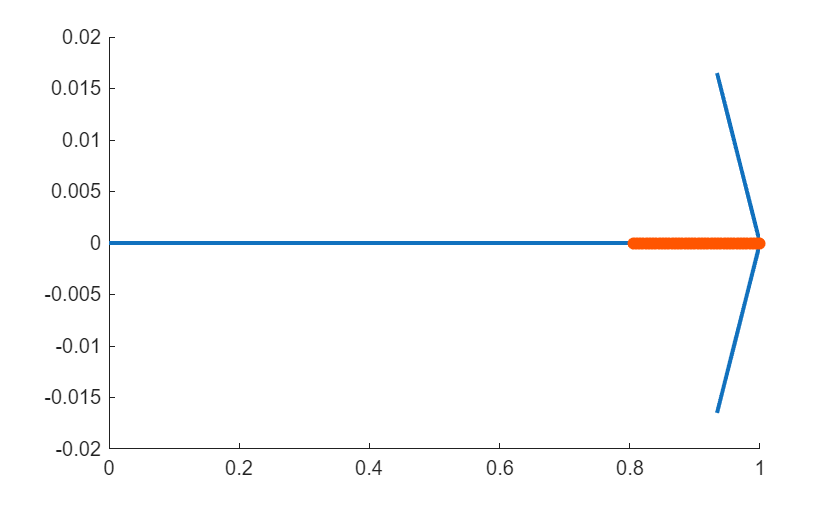

road = nasch.Road();
road.draw();
for k = 2:50
    road.update();
    road.draw();
end

## map class (simple examples)

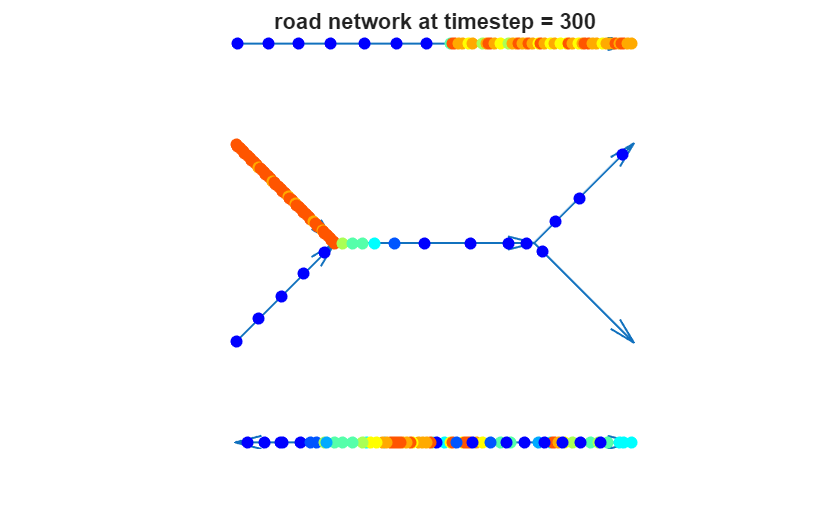

node1 = [    1     ,   3   4  ,   5   6    7   8    8     ];
node2 = [    2     ,   4   3  ,   7   7    8   9   10     ];
times = [    2     ,   0   0  ,   2   2    0   1    1     ];
nodex = [  -1  +1  ,  -1  +1  ,  -1  -1  -.5 +.5   +1  +1 ]*100;
nodey = [  +1  +1  ,  -1  -1  , -.5 +.5    0   0  -.5 +.5 ]*100;
%       \_________/ \_________/ \_________________________/
%         one-way     two-way         Split+Join
%         2 nodes     2 nodes         6 nodes
%         1 street    2 streets       5 streets
map = nasch.Map("node1",node1,"node2",node2,"nodex",nodex,"nodey",nodey,"times",times);
map.draw();
for k = 2:300
    map.update();
    map.draw();
end

## map class (small topology)

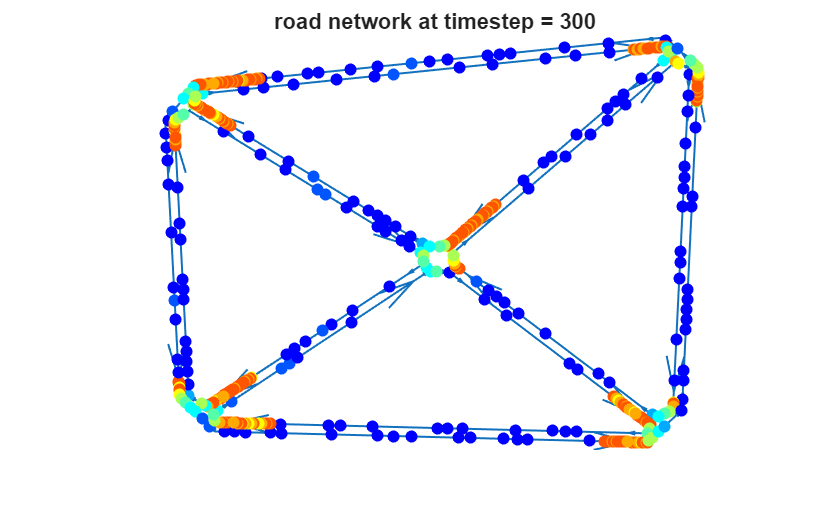

% run editor using: nasch.editor.MapEditor()
map = nasch.Map("file","test","density",0.1);
map.draw();
for k = 2:300
    map.update();
    map.draw();
end

## map class (random topology)

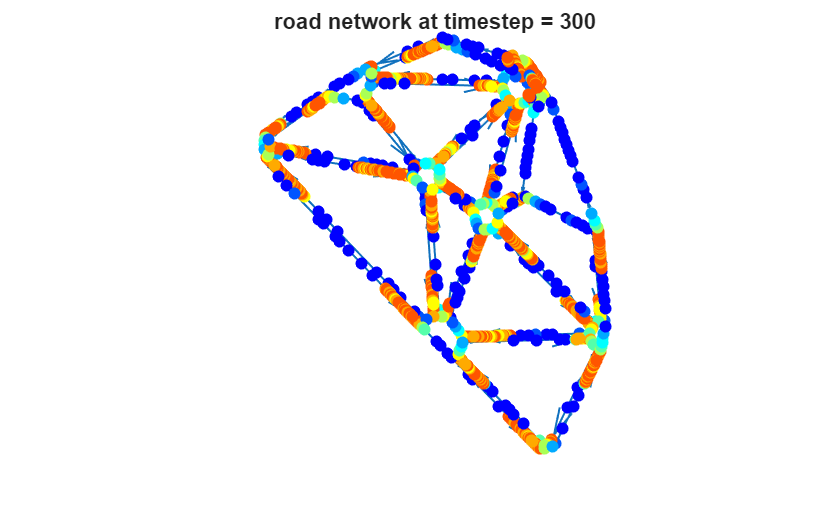

map = nasch.Map();
map.draw();
for k = 2:300
    map.update();
    map.draw();
end